%% AAE 532 HW 4 Problem 4
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps4';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
format shortEng;

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
moon = planet_consts.moon;  % structure of moon
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% Find characterisitics
mu = moon.gp;  % gravitational parameter
a = 7050;  % semi major axis [km]

r_p = 800;  
e = r_p/a + 1;
p = a * (e^2 - 1)

p =      1.6908e+003


b = a * sqrt(e^2 - 1)

b =      3.4525e+003


h = sqrt(mu * p)

h =      2.8792e+003


FBA = 180 - 2*asind(b / (r_p + a))

FBA =    127.8160e+000


v_inf = sqrt(mu / a)

v_inf =    833.9261e-003


En = mu / 2 / a

En =    347.7164e-003


% at TA = -60 deg current time
TA_curr = -60;
r_curr = p / (1 + e*cosd(TA_curr));
v_curr = vis_viva(r_curr, -a, mu);
FPA_curr = -acosd(h / r_curr / v_curr);
H_curr = acosh((a + r_curr) / a / e)

H_curr =    269.1736e-003


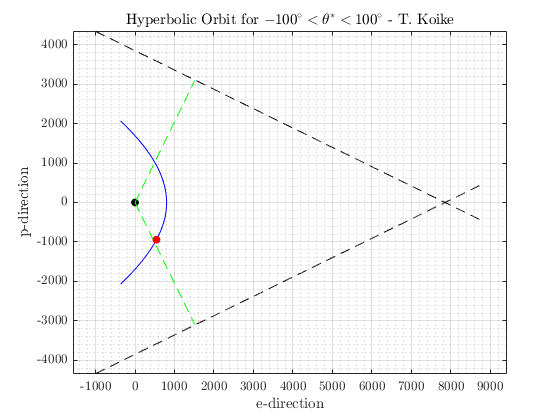

% (b) Plotting
% Hyperbola
TA = -100:1:100;
R = p ./ (1 + e*cosd(TA));
X = R .* cosd(TA);
Y = R .* sind(TA);

fig1 = figure("Renderer","painters");
plot(X, Y, '-b')
title('Hyperbolic Orbit for $-100^{\circ}<\theta^*<100^{\circ}$ - T. Koike')
xlabel('e-direction')
ylabel('p-direction')
grid on; grid minor; box on; axis equal; hold on;

% Asymptotes
x_asymp = -1000:(a*e+1000);
y_asymp_p = sqrt(e^2 - 1)*(x_asymp - a*e);
y_asymp_n = -sqrt(e^2 - 1)*(x_asymp - a*e);

plot(x_asymp, y_asymp_p, '--k')
plot(x_asymp, y_asymp_n, '--k')

% Center
plot(0, 0, '.k', 'MarkerSize', 20)

% b line
x_b = 0:1513;
y_bp = 1/sqrt(e^2-1) .* x_b;
y_bn = -1/sqrt(e^2-1) .* x_b;

plot(x_b, y_bp, '--g')
plot(x_b, y_bn, '--g')

% Plot TA=-60
Xi = X(TA==-60);
Yi = Y(TA==-60);
plot(Xi, Yi, '.r', 'MarkerSize', 20)
hold off
saveas(fig1, fullfile(fdir, 'p4_hyperbola.png'))

% at TA = 100 deg current time
TA_curr = 100;
r_curr = p / (1 + e*cosd(TA_curr));

r_curr =      2.0961e+003


v_curr = vis_viva(r_curr, -a, mu);

v_curr =      2.3181e+000


FPA_curr = acosd(h / r_curr / v_curr);

FPA_curr =     53.6612e+000
